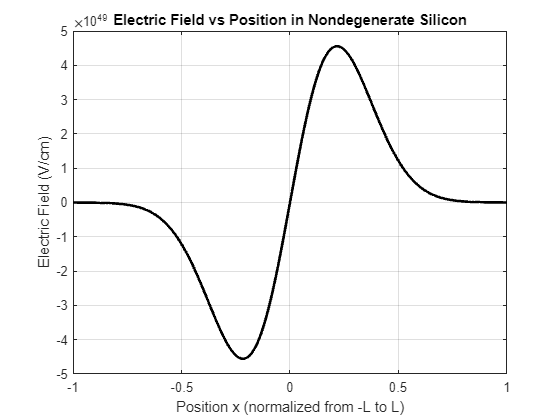

% Constants
k = 8.617e-5;  % Boltzmann constant in eV/K
T = 300;       % Temperature in K
q = 1.602e-19; % Elementary charge in C
L = 1;         % Normalized half-length of the semiconductor
Eg = 1.1;      % Bandgap of Silicon in eV
ni = 1.5e10;   % Intrinsic carrier concentration for Silicon at 300 K in cm^-3
V_T = k * T / q; % Thermal voltage in V

% Einstein relation for mobility and diffusion coefficient
D_N = V_T; % For simplicity, assume mobility is such that D_N = V_T (units of cm^2/s)

% Position range
x = linspace(-L, L, 1000);

% Approximate |E_F - E_i| with a quadratic function of x
A = Eg / (4 * L^2);
E_F_minus_E_i = A * (L^2 - x.^2);

% Calculate the gradient of the carrier concentration
dn_dx = -2 * A .* x .* ni .* exp((E_F_minus_E_i) / (V_T * q));

% Calculate the electric field from the gradient of the carrier concentration
% E(x) is proportional to the spatial derivative of the band bending, which is dn_dx
E = -D_N * dn_dx / q; % Neglecting the sign, since we're interested in the magnitude

% Plotting the electric field E(x) versus position x
figure;
plot(x, E, 'k', 'LineWidth', 2);
title('Electric Field vs Position in Nondegenerate Silicon');
xlabel('Position x (normalized from -L to L)');
ylabel('Electric Field (V/cm)');
grid on;